# Logistic Growth with Diffusive Coupling (LWD model)

This project studies the **Logistic Growth with Diffusive Coupling (LWD model)** process on networks, implemented in MATLAB as a **Live Script (.mlx)** for clarity and reproducibility.


$$\dot{x}_i
\;=\;
r\,x_i\!\left(1-\frac{x_i}{K}\right)
\;+\; D\sum_{j=1}^N L_{ij}\,x_j,
\qquad 1\le i\le N .$$


Here $x_i(t)\in[0,K]$ represents the population density or state variable at node i. The logistic term $r x_i(1 - x_i/K)$ enforces local self-regulation toward the carrying capacity K, while the diffusive term  $D \sum_j L_{ij} x_j (where  ~L = \mathrm{diag}(\deg) - A)$ drives spatial redistribution across the network. This formulation generalizes logistic growth to networked settings, capturing diffusion, synchronization, and nonlinear stabilization effects.

clearvars; close all; clc; rng(1);

%% ---- Style ------------------------------------------------------------
Style.FontName      = pick_font('Roboto','Helvetica');
Style.BaseFS        = 10;
Style.LabelFS       = 12;
Style.TitleFS       = 13;
Style.AxisLineWidth = 0.75;

% Line widths
Style.LW_full = 1.8;
Style.LW_ssm  = 1.3;

% Colors
Style.ColFull = [0.10 0.10 0.10];
Style.ColSSM  = [  0   114 178;
                  230   159   0;
                   86   180 233;
                  204   121 167;
                   51   160  44 ]/255;
Style.MarkersSSM = {'o','o','o','o','o'};

% Network visual style
Style.NetNode       = [0.08 0.08 0.08];
Style.NetEdge       = [93 226 231]/255;
Style.NetEdgeAlpha  = 0.65;
Style.NetNodeSize   = 4.2;

apply_pub_defaults(Style);

## (a) Parameters

N       = 200;     % number of nodes
r       = 1.0;     % logistic growth rate
Kcap    = 1.0;     % carrying capacity
D       = 0.05;    % diffusion coefficient
Kdeg    = 6;       % target mean degree
p       = Kdeg/(N-1); % ER edge probability
orders      = [2, 5, 10, 15, 20];
appr_order  = max(orders);
q0_mag      = 0.05;
tf      = 20;      
nsteps  = 1000;

## (b) ER network

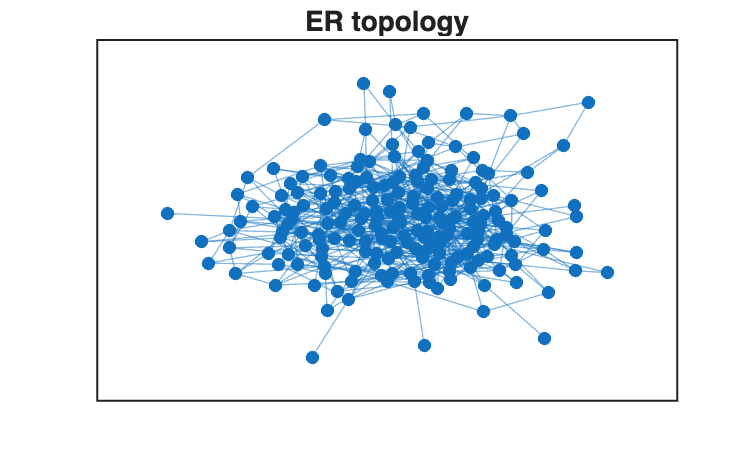

A_er = rand(N) < p;
A_er = triu(A_er,1);
A_er = A_er + A_er.';
A_er = spones(A_er);
G = graph(A_er);
figure; plot(G,'Layout','force','NodeLabel',{},'MarkerSize',4);title('ER topology');

## (c) Build model & DS

[MatA, MatB, MatF] = build_model_logistic(A_er, r, Kcap, D);
DS = DynamicalSystem(1);
DS.A = MatA; DS.B = MatB; DS.fnl = MatF;
DS.Options.Emax = 2;
DS.Options.Nmax = appr_order;
DS.Options.notation = 'tensor';
DS.Options.sigma = 1000;

## (d) Leading mode & initial condition

[V,~,~] = DS.linear_spectral_analysis();


 The first 2 nonzero eigenvalues are given as 
    1.0000
    0.9638



q0      = q0_mag * sign(V(1,1));
z0_full = q0 * V(:,1);

## (e) Full system trajectory

[tRef, zRef] = time_integration_transient(DS, 2*pi, ...
    'nSteps', nsteps/tf, 'nCycles', tf, ...
    'integrationMethod','ode45', 'outdof', 1:N, 'init', z0_full);

## (f) SSM trajectories

traj_all = cell(numel(orders),1);
R0_for_analytic = [];  % store R0 at max order for diagnostics
R0_max = [];           % store R0 at max order for printing
for k = 1:numel(orders)
    ord = orders(k);
    S   = SSM(DS);
    S.Options.paramStyle = 'graph';
    S.Options.reltol     = 100;
    S.Options.notation   = 'tensor';
    S.choose_E(1);
    [W0, R0] = S.compute_whisker(ord);
    if ord == appr_order
        R0_for_analytic = R0;
        R0_max = R0;
    end
    traj_all{k} = transient_traj_on_auto_ssm( ...
                     DS, 1, W0, R0, tf, nsteps, 1:N, [], q0);
end

sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 3.38E-01 MB


sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 3.38E-01 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.51E-01 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.62E-01 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 3.74E-01 MB


sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 3.39E-01 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.51E-01 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.62E-01 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 3.74E-01 MB
Computing autonomous whisker at order 6
1 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 3.87E-01 MB
Computing autonomous whisker at order 7
1 (near) inner resonance(s) detecte

sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 3.39E-01 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.51E-01 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.62E-01 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 3.74E-01 MB
Computing autonomous whisker at order 6
1 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 3.87E-01 MB
Computing autonomous whisker at order 7
1 (near) inner resonance(s) detecte

sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 3.39E-01 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.52E-01 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.62E-01 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 3.74E-01 MB
Computing autonomous whisker at order 6
1 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 3.87E-01 MB
Computing autonomous whisker at order 7
1 (near) inner resonance(s) detecte

## (g) Node-level dynamics

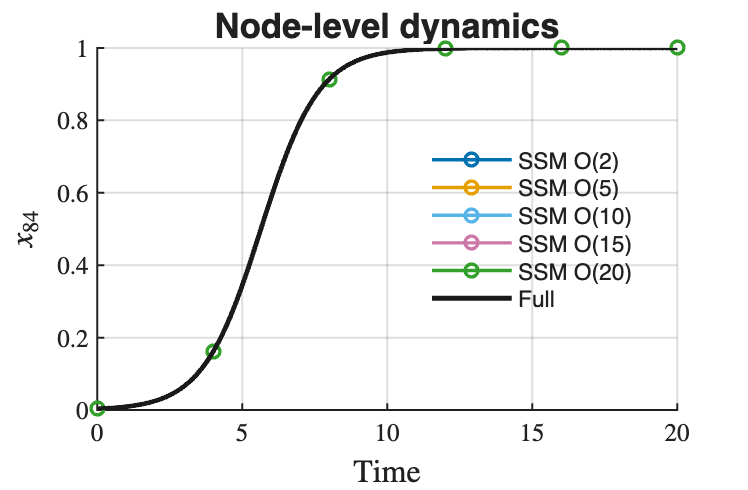

rng(1); idnode = randi(N);
figN = figure('Color','w','Position',[120 120 640 420]);
axN  = axes(figN); hold(axN,'on');

for k = 1:numel(orders)
    c = Style.ColSSM(k,:);
    tk = traj_all{k}.time;
    xk = traj_all{k}.phy(:,idnode);
    plot(axN, tk, xk, '-', ...
        'Color', c, 'LineWidth', Style.LW_ssm, ...
        'Marker', Style.MarkersSSM{k}, ...
        'MarkerIndices', 1:max(1,round(numel(tk)/5)):numel(tk), ...
        'MarkerSize', 4.8, ...
        'DisplayName', sprintf('SSM O(%d)', orders(k)));
end

plot(axN, tRef, zRef(:,idnode), '-', ...
     'Color', Style.ColFull, 'LineWidth', Style.LW_full, ...
     'DisplayName','Full');

xlabel(axN, 'Time', 'FontSize',Style.LabelFS,'Interpreter','latex');
ylabel(axN, sprintf('$x_{%d}$',idnode), ...
       'FontSize',Style.LabelFS,'Interpreter','latex');
set(axN,'TickLabelInterpreter','latex','LineWidth',Style.AxisLineWidth);
title(axN, 'Node-level dynamics','FontSize',Style.TitleFS);
legend(axN,'Location','best','Box','off');
grid(axN,'on');

## (h) Mean dynamics 

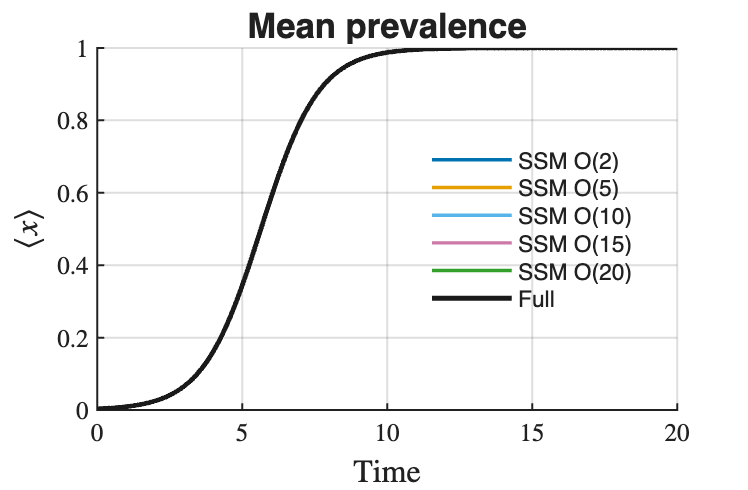

figM = figure('Color','w','Position',[140 140 640 420]);
axM  = axes(figM); hold(axM,'on');
for k = 1:numel(orders)
    tk = traj_all{k}.time;
    mk = mean(traj_all{k}.phy,2);
    plot(axM, tk, mk, '-', ...
        'Color', Style.ColSSM(k,:), 'LineWidth', Style.LW_ssm, ...
        'DisplayName', sprintf('SSM O(%d)', orders(k)));
end
t_full = tRef(:);
m_full = mean(zRef,2);
plot(axM, tRef, m_full, '-', ...
     'Color', Style.ColFull, 'LineWidth', Style.LW_full, ...
     'DisplayName','Full');

xlabel(axM, 'Time', 'FontSize',Style.LabelFS,'Interpreter','latex');
ylabel(axM, '$\langle x\rangle$', ...
       'FontSize',Style.LabelFS,'Interpreter','latex');
set(axM,'TickLabelInterpreter','latex','LineWidth',Style.AxisLineWidth);
title(axM, 'Mean prevalence','FontSize',Style.TitleFS);
legend(axM,'Location','best','Box','off');
grid(axM,'on');

## (i) Analytical domain

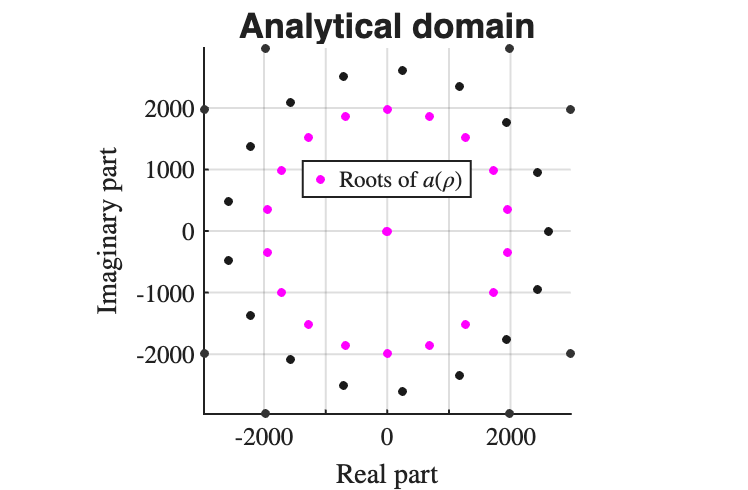

figA = figure('Color','w','Position',[160 160 640 420]);
axA  = axes(figA); hold(axA,'on');

plot_analytical_domain(appr_order, R0_for_analytic);

set(axA,'TickLabelInterpreter','latex','LineWidth',Style.AxisLineWidth);
title(axA, 'Analytical domain','FontSize',Style.TitleFS);
grid(axA,'on');

## (j) Local functions 

function [A, B, F] = build_model_logistic(adj, r, Kcap, D)
    n   = size(adj,1);
    deg = sum(adj,2);
    B   = speye(n);
    A   = diag(r - D*deg) + D*adj;
    idx  = (1:n)';
    subs = [idx, idx, idx];
    vals = -r/Kcap * ones(n,1);
    F2   = sptensor(subs, vals, [n n n]);
    F    = {F2};
end


function apply_pub_defaults(S)
    set(groot,'defaultAxesFontName',S.FontName);
    set(groot,'defaultAxesFontSize',S.BaseFS);
    set(groot,'defaultAxesLineWidth',S.AxisLineWidth);
    set(groot,'defaultAxesTickDir','out');
    set(groot,'defaultAxesBox','off');
end

function name = pick_font(primary, fallback)
    f = listfonts; name = fallback;
    if any(strcmpi(f, primary)), name = primary; end
end

function plot_analytical_domain(appr_order, R_0)
    if appr_order < 1 || ~isstruct(R_0)
        warning('plot_analytical_domain: bad inputs'); return;
    end
    ord0   = floor(appr_order/2);
    ordVec = ord0:appr_order;
    cmap = flipud(gray(max(numel(ordVec),2)));
    holdState = ishold; hold on;

    last_roots = [];
    run_idx = 1;
    for order = ordVec
        p = zeros(1, order+1);
        for j = 1:order
            if j <= numel(R_0) && isfield(R_0(j),'coeffs') && ~isempty(R_0(j).coeffs)
                crow = R_0(j).coeffs(1,:);
                nz   = crow(abs(crow) > 0);
                if ~isempty(nz), p(j+1) = real(nz(1)); end
            end
        end
        rts = roots(flip(p));
        last_roots = rts;
        if order < appr_order
            plot(real(rts), imag(rts), '.', ...
                 'Color', cmap(min(run_idx,size(cmap,1)),:), ...
                 'MarkerSize', 10, 'HandleVisibility','off');
        else
            plot(real(rts), imag(rts), 'm.', 'MarkerSize', 10, ...
                 'LineWidth', 2, 'DisplayName', 'Roots of $a(\rho)$', ...
                 'Color', 'm');
        end
        run_idx = run_idx + 1;
    end
    xlabel('Real part', 'Interpreter','latex');
    ylabel('Imaginary part', 'Interpreter','latex');
    legend('show', 'Interpreter','latex', 'Location','best');
    axis equal; box off;

    if ~isempty(last_roots)
        rho_med = median(abs(last_roots));
        sel     = abs(last_roots) > rho_med;
        if any(sel)
            rho = mean(abs(last_roots(sel)));
            if isfinite(rho) && rho > 0
                lim = 1.5 * rho;
                xlim([-lim, lim]); ylim([-lim, lim]);
            end
        end
    end
    if ~holdState, hold off; end
end

**Note:**

For computing quantitative error metrics such as time-to-steady-state error, node-level MAE, spatial correlation, and mean-prevalence MSE, one can directly implement the procedure provided in the accompanying file **SIS_demo.mlx**, which illustrates the complete computation pipeline.